EX. 2

clear all

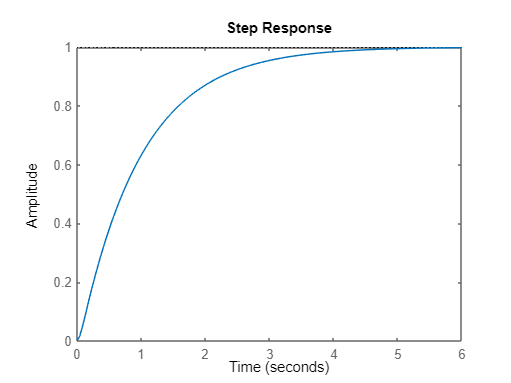

%given data
K=1;
tau=1/25;
D=0;
Kv=100;
ess=1/Kv;
%transfer funtion
s=tf('s');
%open loop system
%Gp = K/(s*(tau*s+1));
num=K;
den=[tau,1,0];
Gp=tf(num,den);
%closed loop system
Gp_closed=feedback(Gp,1);
%plotting closed_loop step
step(Gp_closed)

%displaying step info
stepinfo(Gp_closed)

ans = struct with fields:
         RiseTime: 2.1071
    TransientTime: 3.7915
     SettlingTime: 3.7915
      SettlingMin: 0.9002
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 7.0166


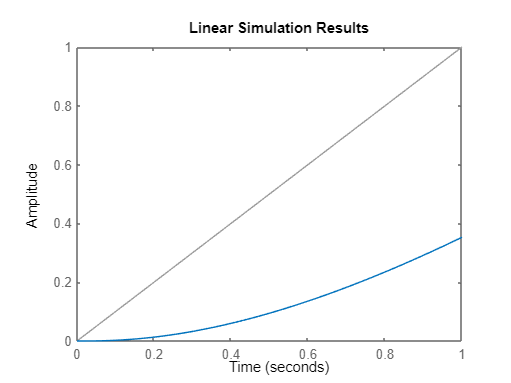

%linear simulation of the original system
t = 0:0.01:1;
lsim(Gp_closed,t,t)

a)

We will prepare the compensator using Ziegler-Nichols method for PID tunning:

It is performed by setting the I (integral) and D (derivative) gains to zero. The P (proportional) gain (Kp) is then increased until it reaches the ultimate gain (Ku), at which the output of the control loop has stable and consistent oscillations. Ku and the oscillation period Tu are then used to set the P, I, and D gains depending on the type of controller used and behaviour desired:

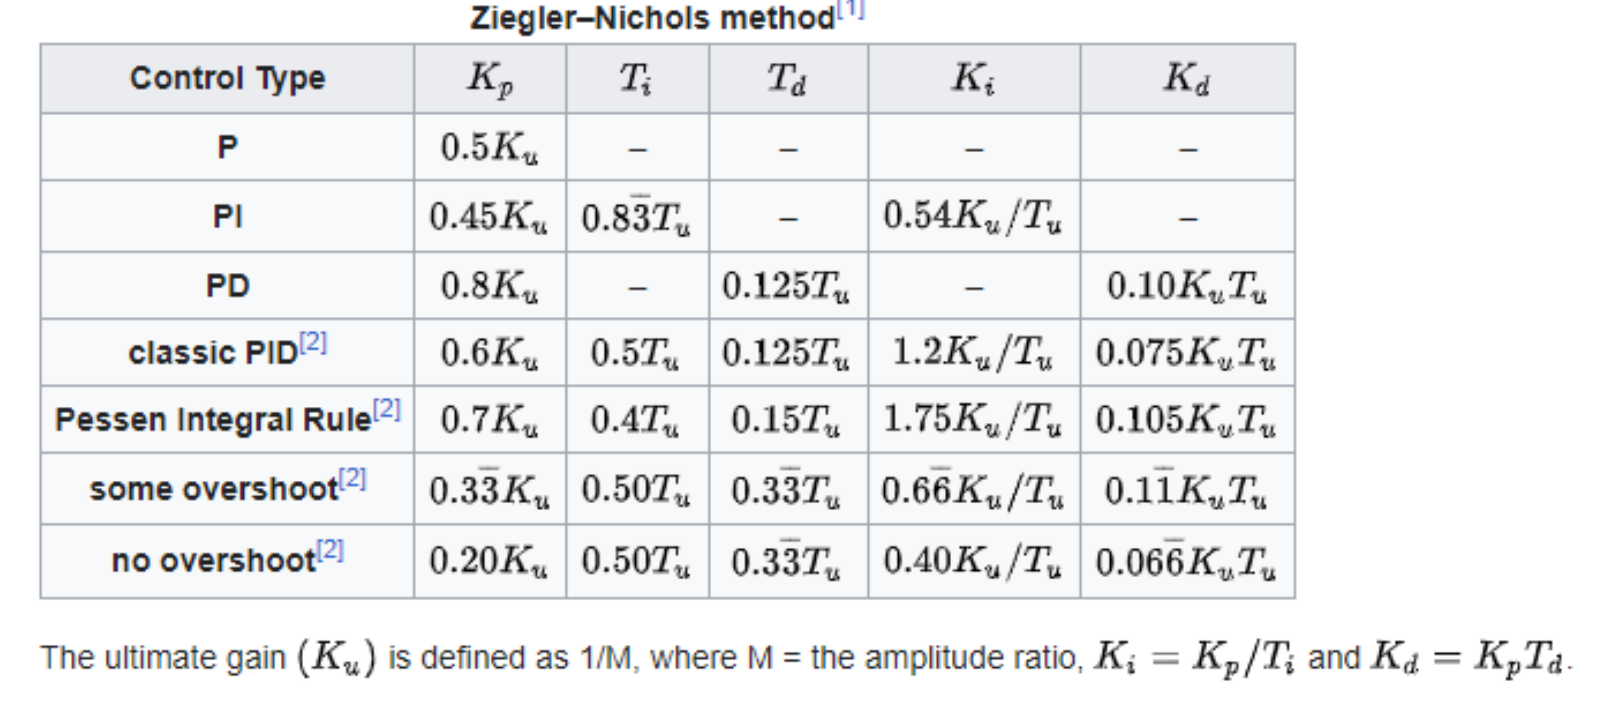

rys.6 Table for PID tunning using Ziegler-Nichols method.

• The ultimate gain Ku can be read from the rlocus plot presented below. It lays on the crossing of the locus line and the imaginary axis.

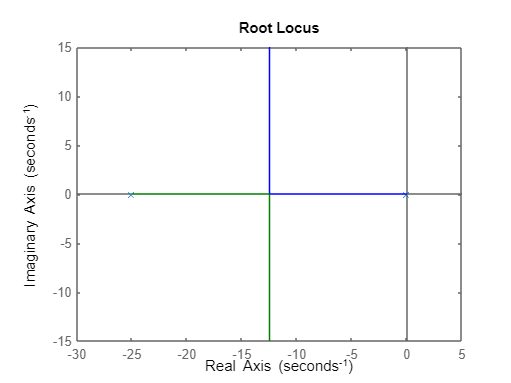

rlocus(Gp)

The value for our system is: 

Ku=0;
